# A simulation of a differential phase shift protocol satellite pass

## 1. Choose parameters

wavelength=780;                                                            %wavelength is measured in nm
transmitter_telescope_diameter=0.1;                                        %diameters are measured in m
receiver_telescope_diameter=1;                                           
time_gate_width=1E-10;                                                      %times are measured in s
spectral_filter_width=1;                                                  %consistemt with wavelength, spectral width is measured in nm
repetition_rate = 1E8;  
state_probabilities = [0.9,0.1];
mean_photon_numbers = 0.9;

## 2. Construct components

%2.1 Satellite
%2.1.1 Source
Transmitter_Source=components.Source(wavelength,...
                          'Repetition_Rate',repetition_rate,...
                          'MPN_Signal',mean_photon_numbers,...
                          'Probability_Signal',state_probabilities(1),...
                          'Probability_Decoy',state_probabilities(2));        %we use default values to simplify this example

%2.1.2 Transmitter telescope
Transmitter_Telescope=components.Telescope(transmitter_telescope_diameter);           %do not need to specify wavelength as this will be set by satellite object

%2.1.3 Construct satellite
StartTime = datetime(2022,12,25,6,0,0);
StopTime = datetime(2022,12,25,7,0,0);
SampleTime = 1;
SimSatellite=nodes.Satellite(Transmitter_Telescope,...
                        'Source',Transmitter_Source,...
                        'SemiMajorAxis',500E3 + earthRadius,...             %mean orbital radius = Altitude + Earth radius
                        'eccentricity',0,...                                %measure of ellipticity of the orbit, for circular, =0
                        'inclination',97.065055549393420,...                  %inclination of orbit in deg- set by sun synchronicity
                        'rightAscensionOfAscendingNode',-1.5,...            %measure of location of orbit in longitude
                        'argumentOfPeriapsis',0,...                         %measurement of location of ellipse nature of orbit in longitude, irrelevant for circular orbits
                        'trueAnomaly',0,...                                 %initial position through orbit of satellite
                        'StartTime',StartTime,...                           %start of simulation
                        'StopTime',StopTime,...                             %end of simulation
                        'sampleTime',SampleTime);                           %simulation interval in s

%2.2 Ground station
%2.2.1 Detector
DPS_Detector=components.Detector(wavelength,Transmitter_Source.repetition_rate,time_gate_width,spectral_filter_width,...
    "Preset",'MicroPhotonDevices');
%need to provide repetition rate in order to compute QBER and loss due to
%time gating
%NOTE only detectors with the 'Visibility' property can be used for COW

%2.2.2 Receiver telescope
Receiver_Telescope=components.Telescope(receiver_telescope_diameter);

%2.2.3 construct ground station, use Chilbolton as an example
SimGround_Station=nodes.GroundStation(Receiver_Telescope,...
                                'Detector',DPS_Detector,...
                                'LLA',[55.909723, -3.319995,10],...
                                'Name','Heriot-Watt');
%no need to provide an environment. we will use the default

## 3 Compose and run the PassSimulation

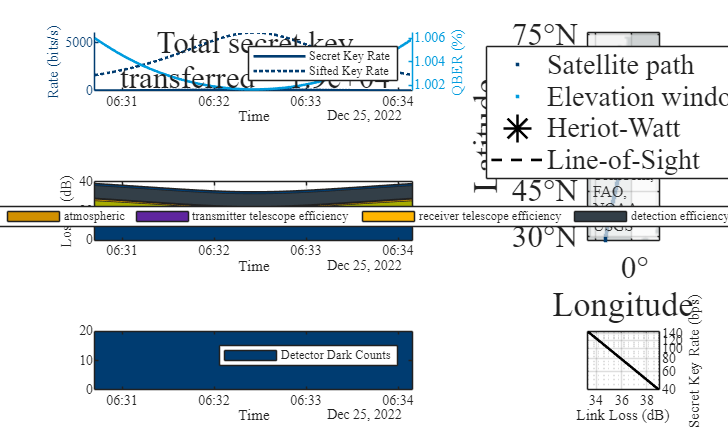

SimResults = nodes.qkdPassSimulation(SimGround_Station,SimSatellite,protocol.DPS);
plot(SimResults);